Estimate impulse response

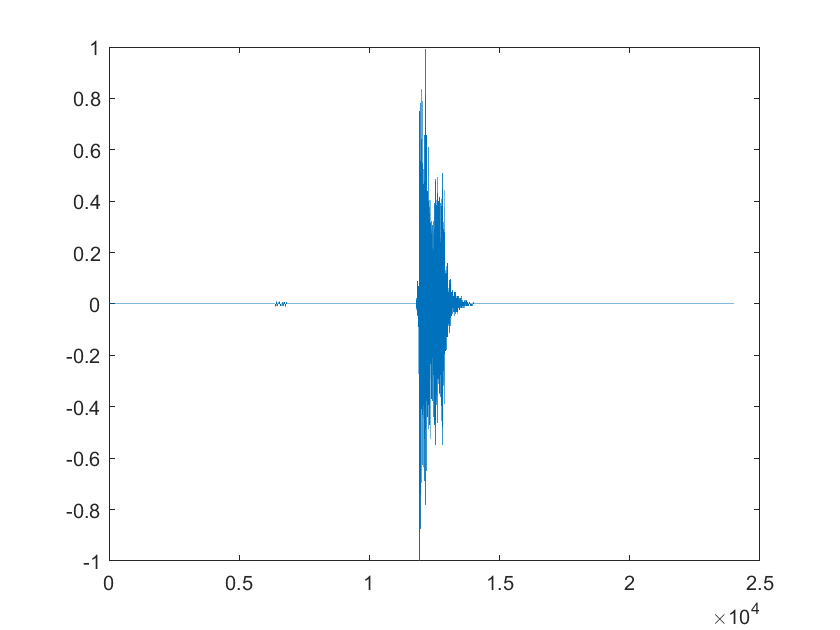

% recObj = audiorecorder;
% disp('start receiving.');
% recordblocking(recObj, 3);
% disp('end receiving');
% h_received = getaudiodata(recObj);
plot(h_received);

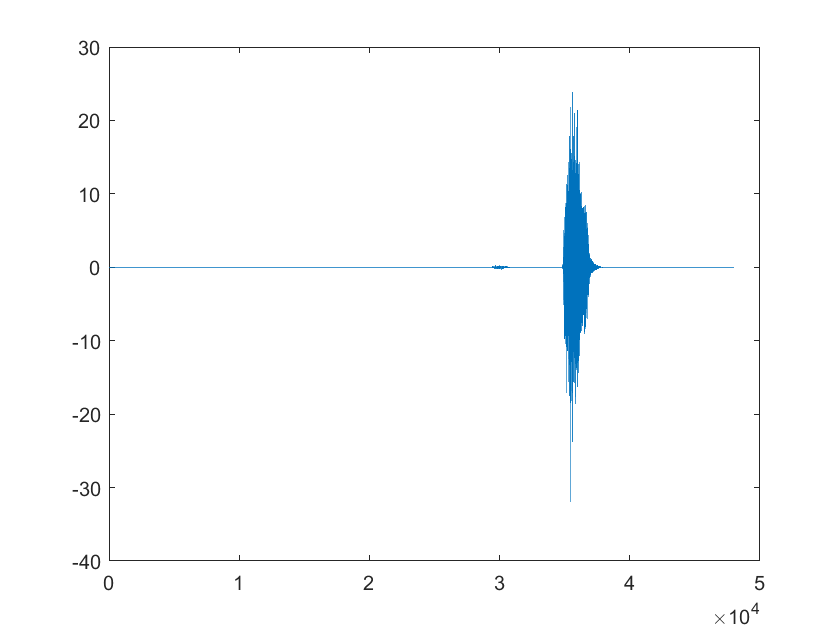

h_xcorr = xcorr(h_received, n);
plot(h_xcorr)

for i=1:size(h_xcorr)
    if h_xcorr(i) > 1
        break
    end
end
for j=size(h_xcorr):-1:1
    if h_xcorr(j) > 1
        break
    end
end
h = h_xcorr(i:j)

h =     1.2131
    1.2010
   -0.0725
    0.3224
   -0.1037
   -1.6572
   -2.5563
   -2.2311
   -0.4965
    1.6319


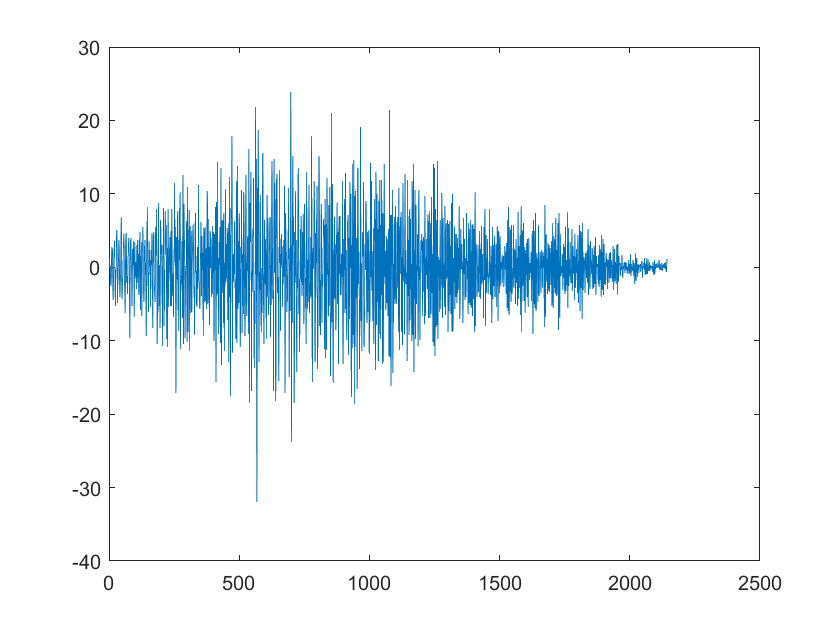

plot(h)

Text decoding

% recObj = audiorecorder;
% disp('start receiving.');
% recordblocking(recObj, 8);
% disp('end receiving');
% y = getaudiodata(recObj);
% plot(y);

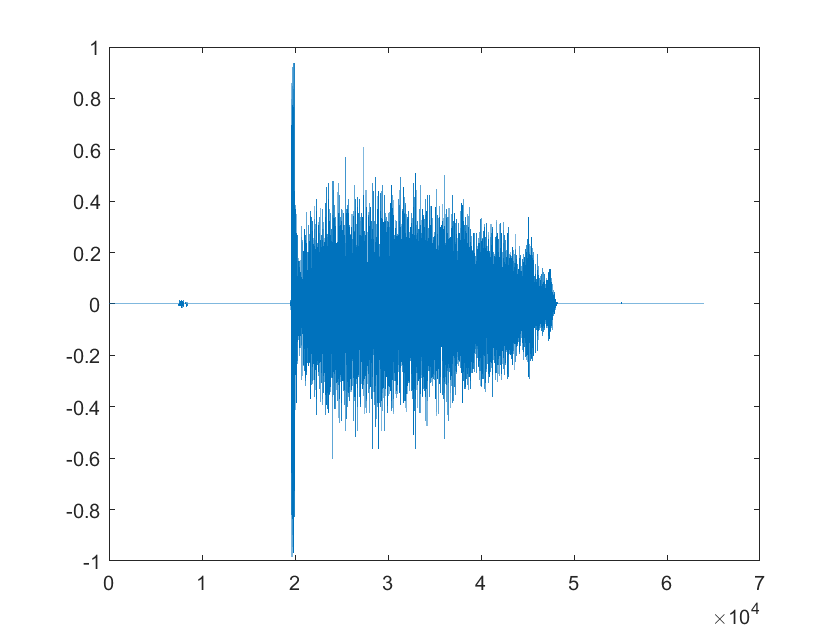

plot(y);

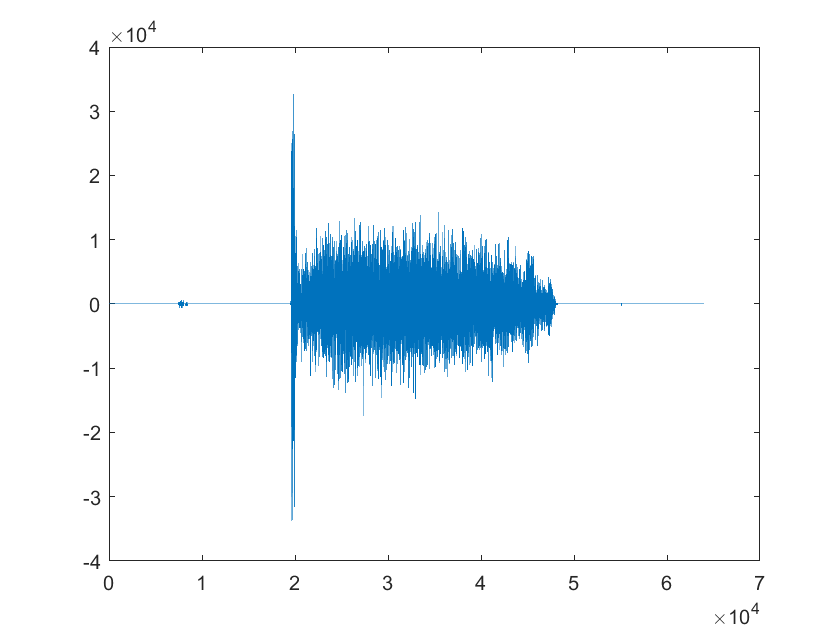

fc = 2000; %2kHz
time = linspace(0,1,length(y));
y_c = y.*cos(2*pi*fc*time.');
y_s = y.*sin(2*pi*fc*time.')*j;
y_b = y_c + y_s;
y_b = lowpass(y_b, .5);
plot(y_b);

for i=1:size(y_b)
    if y_b(i) > .25*10^4
        y_b(i) = 1;
    elseif y_b(i) < -.25*10^4
        y_b(i) = -1;
    else
        y_b(i) = 0;
    end
end
y_b = nonzeros(y_b);
for i=1:size(y_b)
    if y_b(i) == -1
        y_b(i) = 0;
    end
end
binary = num2str(y_b(1:10073));
binary = binary(binary~=' ');
mess = char(bin2dec(reshape(binary,7,[]).').')

mess =     'xC~|p`P>0?A~ @@vx>x|a>cGAxp>#GCDob^7qasxG9g201p9199qfcNNIxLt9acGf821cfv1t:>@?3Fpy`OCx>N#`o <{2gg`oAhg1~d8?cpCV`panp>'8R><
     x|>
     NC`|?1lg	x0p&`<p<CL8V|Fcl89GH<Xh8C9AcAx@cDO@~Fx><? cpa_|`qbO@lnGaxxAx!ayx\t0ApPX4@|/@xdi_	pXl?x?p\xxp@|ZOLAAp|3aeA<qaccp~;GG`;`gG~x'La`?`<9N`@9`Ocx?x~ ?`Cp@`~#F p ~@Bx0?|F<`6?@|~~7`~ Csax|l ~Gm0|<p;@dN06Ccx{ pA yxC`/xaAx{`>'A`c@>A|<G@pp`.g |xG`8pq? 	`~;`<?7b<p>	px<pCyX|
     Xx0>y,{H|px3FpY`?@[ap:<_s`x6X? CfA|\lax> ~0`~O s@Gc<8@>FLG+9yp?L7CGp8Qqx}  |xap``5p
     5dppp3qAOAap7`q@f>p~Ay7iX|s|p:1GqA~yy8xa|La7|8>Igcp=@|?A~ xv<`
     Cp?&CxpQbNay|c>#Cxq| pp\0=Gxxa{?Awyecxp?A|<xA'@?Cx3acCL8?L;a``|gXax8'`r><CkAGG`x~C|0`Apx<cCx8`~^<CcO sCqG w~q<pp<cH><p1xp|O`<>0pC|icC~<Ccr >apx<C|>z`|ax8x1|8?``a|xgAp<qpxc{CCxp?`yLEpsqaypaqx0Ap? yG?Al|pawAx|o `p8|<8`CFG@ccApypx`>AxCX?p``<O?`|~xc|>p|Cfgsg9x`83d'GFC@<>pAwCgCa_s`~p9p|p><8xx8<xG&?sqxpwCpCay ~Aqax80?cxp>0px|<`x=caybsOcGa`3f`c>`xCpxG|0|\|8<?p|>aOqppxq~>Gaq`pcC<<  BCpxqi'


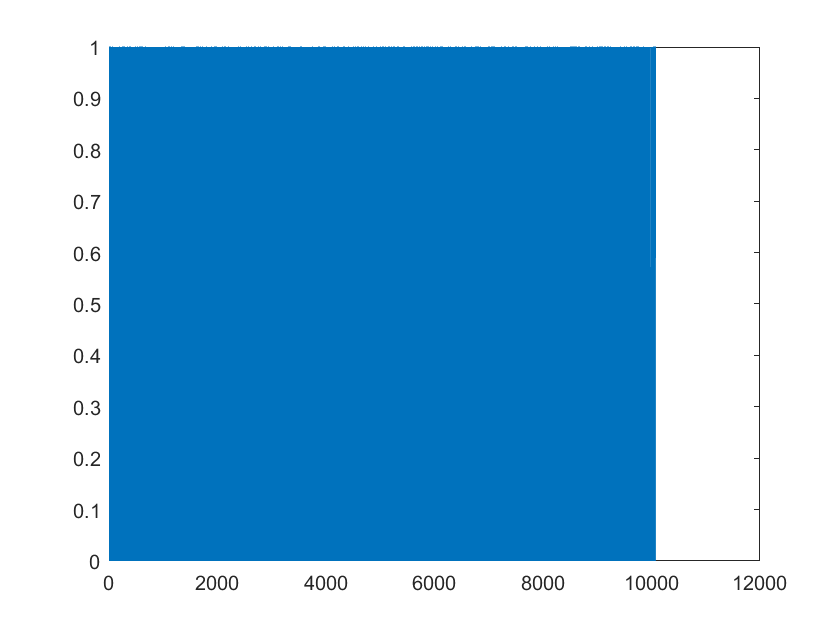

plot(y_b);

n: input white noise

h_received: received response from white noise input

h: estimated channel response

y: received response from encoded text message